# `MFC: Multi-Robot Forest Coverage Algorithm`

- STEP 1: Create a connected map and respective graph.

- STEP 2: Remove all edges of weight greater than *B*.

- STEP 3: *M ← MST* of graph obtained from *G* by contracting roots in *R *to a single node.

- STEP 4: ${\left\lbrace T_i \right\rbrace }_i$ ← forest obtained from *M* by un-contracting roots in *R.*

- STEP 5: Edge-decompose each tree $T_i$ into trees ${\left\lbrace S_j^i \right\rbrace }_j +L_i$ such that $w\left(S_i^j \right)\;\epsilon \;\left\lbrack B,2B\right)$, for every *j*, and     $w\left(L_i \right)<B$.

- STEP 6: Try to match the trees${\left\lbrace S_j^i \right\rbrace }_{i,j}$ to roots, subject to the constraint that a tree $S_j^i$ may be matched only to roots of distance at most *B* from it. 

- STEP 7: If not all trees are matched, then return fail: “*B* is too low”.

- STEP 8: If every tree is matched, then return success: set of trees where each tree consists of $S_{i,j}$ , its matched root *r*, and the leftover tree *L* (if any) that contains the root *r*.

- STEP 9: Given each spanning tree, extract the route for each drone to circumnavigate the tree in clockwise direction

## STEP 1)  Create a connected map and respective graph.

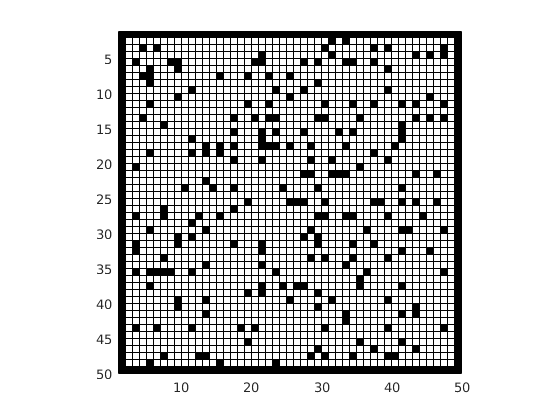

clc;
clear;
% Generate map
global map numeredMap N M B R numeredRoots numeredRootsCell numRobots walldensity;
N = 49;
M = N;
walldensity = 0.1;
numRobots = 2;
[map, numeredMap] = generateMap();
displayMap(map);

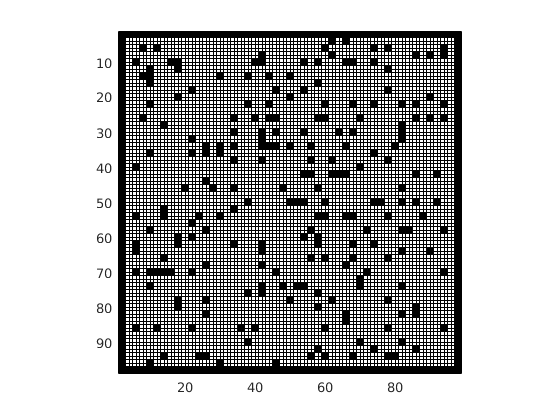

% Create graph based on the map
[G,s,t,weight] = generateGraph();
% Convert into large map (each cell becomes a 4x4)
map1 = mapMFC();
displayMap(map1);

Set parameters: 

- Number of robots and their position inside the grid.

- Bound B on the weight of each spanning tree: it should be greater than *w_max *(maximum weight of an edge) and smaller than *w_sum* (sum of all edge weight in the graph).

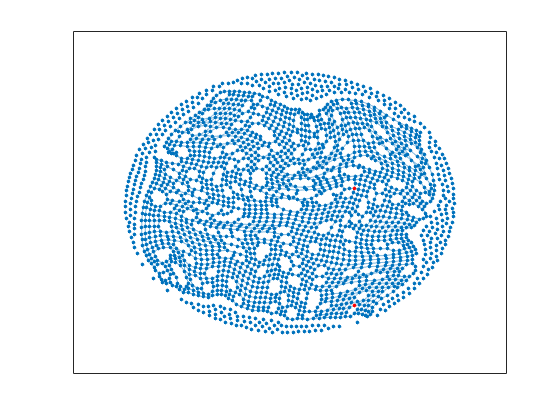

% Spawn randomly a number of robots inside the map
R = spawnRobots();
[numeredRoots, numeredRootsCell]  = convertR();
% Bound B: an upper limit on the weight of each tree
w_max = 4;
w_sum = 4*nnz(~map);
% B = 60; 
% Highlight the roots in the graph
p = plot(G);
layout(p,"force","UseGravity",true)
highlight(p, numeredRootsCell,'NodeColor','r')

## STEP 2)  Remove all the edge greter than the bound B.

[G1,s1,t1,weight1] = removeEdgeGreaterThanB(G,s,t,weight); 

## STEP 3) Contract roots to a single node and find M (Minimum Spanning Tree).

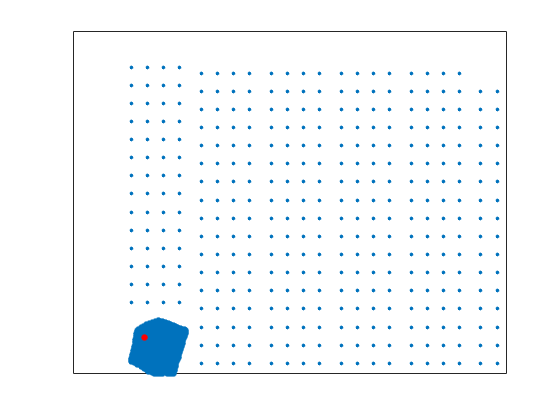

% A new node, called 'contractedRoots', is introduced: it has 0-weight edge
% with the roots, meaning that these roots are contracted into a single
% node.
[G2,s2,t2,weight2] = groupRoots(G1,s1,t1,weight1);
p2 = plot(G2);
[M2,pred2] = minspantree(G2,'Root',findnode(G2,'contractedRoots'));
highlight(p2,M2);
highlight(p2, 'contractedRoots','NodeColor','r');

## STEP 4) Find forest obtained from M by un-contracting roots in R.

% Step 4: find forest obtained from M by un-contracting roots in R

% forest_M is the collection of the subtree of the MST starting from the roots
[forest_M,G3,M3] = obtainForest(G2,M2);
% Order the trees in Forest in increasing order (as the root in R)
forest_M = orderForest(forest_M);

## STEP 5) Edge-decompose each tree.

%  Step 4: Edge-decompose each tree T_i into trees (S_ij + L_i) such that
%          w(S_ij) ∈ [B,2B[, for every j, and w(L_i) < B.

% Define as global leftover and non-leftovers
global map numeredMap N M B R numeredRoots numeredRootsCell numRobots;
global leftovers nonLeftovers rootNonLeftovers rootIdx subTree treeRootedR;
[leftovers, nonLeftovers, rootNonLeftovers] = deal({});


% For each root(tree rooted in r)
for i = 1:length(forest_M)
    % Assign to subTree the tree rooted in r
    rootIdx = i;
    subTree = forest_M{rootIdx};
    treeRootedR = subTree;
    leftover = decomposeEachTree(numeredRootsCell{rootIdx});
    % if is empty then add to the leftover only the root r
    if height(leftover.Nodes) == 0
        % if empty, add the root r
        leftovers{end+1} = subgraph(forest_M{rootIdx}, numeredRootsCell{rootIdx});
    else
        leftovers{end+1} = leftover;
    end
end
% treeEdgeDecomposition(forest_M);

## STEP 6) Try to match the trees${\left\lbrace S_j^i \right\rbrace }_{i,j}$ to roots -> Maximum Bi-Partite matching.

A Bi-Partite graph is constructed as follows: 

- One side of the vertex set is R and the other side consists of nodes representing the trees ${\left\lbrace S_j^i \right\rbrace }_{i,j}$.

- An edge connects a root r and a tree ${\left\lbrace S_j^i \right\rbrace }_{i,j}$  if the distance between $S_j^i$ and *r* is at most *B*. 

- A maximum matching is then computed in this Bi-Partite graph.

## STEP 7) If not all trees are matched, then return fail: “*B* is too low”.

If one or more nonleftover subtrees cannot be matched, report FAILURE.

## STEP 8) If every tree is matched, then return success. 

Return  k-trees where each tree consists of the leftover subtree of the root r, the single nonleftover subtree (if any) matched to the root and weight minimal path (if any) from the non leftover subtree to the leftover subtree.

% Step 6.

% Create Bi-Partite graph with the respective edges.    
% biPartiteGraph = createBiPartiteGraph(G1);

% Find a maximum matching of all non-leftovers subtree to the roots
[proceed, matchR, minimumD] = maxBPM(G1);
% [matching, matchR, minimumD] = maxMio(G1);

% Step 8.
% if matching == length(nonLeftovers)
if proceed == true
    disp("The maximum mat" + ...
        "ching is equal to the number of non-leftover trees -> SUCCESS");
%     kRootedTrees = constructTrees(G1,matchR, minimumD);
    kRootedTrees = newConstruct(G1,matchR,minimumD);
    % Plot sequence of trees
    plotKrooteTrees(kRootedTrees);
    % Plot final map with coloured nodes
    plotFinalMap(G1,kRootedTrees); 
else
    % Step 7.
    disp("FAIL -> The value of B is too low.");
end

## STEP 9 ) Extract the routes for every drone

% Set xy dimension of drones with security offset
dim = 0.5; % m 
[routes, R4] = extractRoute(kRootedTrees, dim);
[minW, maxW] = findWeight(routes);
% % Extract route
% try
%     [routes, R4] = extractRoute(kRootedTrees, dim);
%     [minW, maxW] = findWeight(routes);
% catch
%     warning("The value of B is too low")
% end